**Function Name:** boxy

**Inputs:**

- (cell)  Nx4 cell array of information

**Outputs:**

- (cell) Nx2 of variable being solved for and its value

**Function Description:**

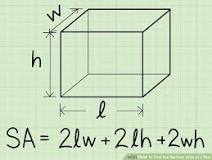

        The columns represent 

- column 1 = the value being solved for ('v' - volume, 'sa' - surface area, 'af' - area of front (hl), 'at' - area of top (wl), 'al' - area of left (hw)

- column 2 = length

- column 3 = width

- column 4 = height

        The first column of each row determines the value that you are solving for. Use columns 2,3 and/or 4 of the row to calculate the value

        Return a Nx2 cell array with the abbreviation of the value that is calculated and that value on each row.

**Example:**

**Test Cases:**

info = [{'v'} {2} {3} {4}
        {'sa'} {1} {3} {2}
        {'af'} {5} {6} {2}
        {'at'} {4} {9} {2}
        {'al'} {3} {7} {4}];
    
res = boxy(info)

rows = 5

res = 5×2 cell array
    {'v' }    {[24]}
    {'sa'}    {[22]}
    {'af'}    {[10]}
    {'at'}    {[36]}
    {'al'}    {[28]}


**Notes:**

**Stallworth's Function Definition:**

function [out] = boxy(info)
    
    [rows, ~] = size(info)
    for r = 1:rows
        calc = info{r,1};
        l = info{r,2};
        w = info{r,3};
        h = info{r,4};
        if isequal(calc,'v')
            out(r,1:2) = [{calc} l*w*h];
        elseif isequal(calc,'sa')
            out(r,1:2) = [{calc} 2*l*w + 2*w*h + 2*l*h];
        elseif isequal(calc,'af')
            out(r,1:2) = [{calc} l*h];
        elseif isequal(calc,'at')
            out(r,1:2) = [{calc} l*w];
        elseif isequal(calc,'al')
            out(r,1:2) = [{calc} w*h];
        end
        
    end

end